# Create Confusion Matrix Chart

Load Fisher's iris data set.

load fisheriris
X = meas;
Y = species;

`X` is a numeric matrix that contains four petal measurements for 150 irises. `Y` is a cell array of character vectors that contains the corresponding iris species. 

Train a *k*-nearest neighbor (KNN) classifier, where the number of nearest neighbors in the predictors (*k*) is 5. A good practice is to standardize numeric predictor data.

Mdl = fitcknn(X,Y,'NumNeighbors',5,'Standardize',1);

Predict the labels of the training data.

predictedY = resubPredict(Mdl);

Create a confusion matrix chart from the true labels `Y` and the predicted labels `predictedY`. 

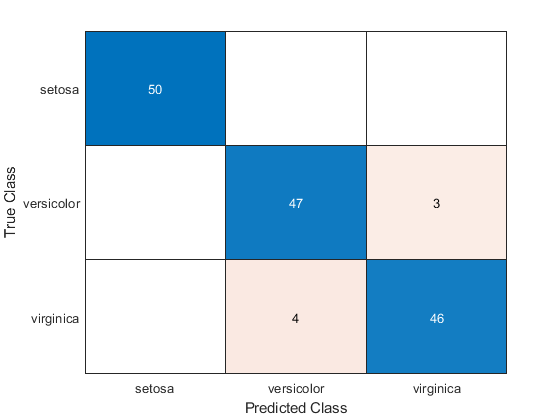

cm = confusionchart(Y,predictedY);

The confusion matrix displays the total number of observations in each cell. The rows of the confusion matrix correspond to the true class, and the columns correspond to the predicted class. Diagonal and off-diagonal cells correspond to correctly and incorrectly classified observations, respectively.

By default, `confusionchart` sorts the classes into their natural order as defined by [`sort`](docid:matlab_ref.bt8nojg-1). In this example, the class labels are character vectors, so `confusionchart` sorts the classes alphabetically. Use [`sortClasses`](docid:stats_ug.mw_d3e13a63-5fe2-4501-b40d-a565d3008b9d) to sort the classes by a specified order or by the confusion matrix values. 

The `NormalizedValues` property contains the values of the confusion matrix. Display these values using dot notation.

cm.NormalizedValues

ans =     50     0     0
     0    47     3
     0     4    46


Modify the appearance and behavior of the confusion matrix chart by changing property values. Add a title. 

cm.Title = 'Iris Flower Classification Using KNN';

Add column and row summaries.

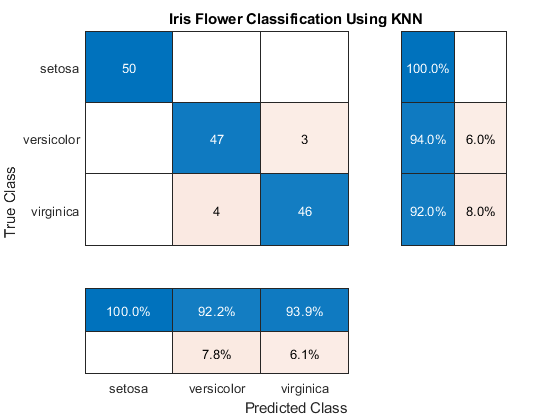

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

A row-normalized row summary displays the percentages of correctly and incorrectly classified observations for each true class. A column-normalized column summary displays the percentages of correctly and incorrectly classified observations for each predicted class.  

*Copyright 2018 The MathWorks, Inc.*